addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\functions')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\data')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\yxx\')

clear; clc;
close all;
load projectData24.mat
k       = 3;                                            % Prediction horizon.
groupNo = 49;                                            % Example group number.
nolags  = 200;
sweek   = 168;
sday    = 24;                                           % Daily season.

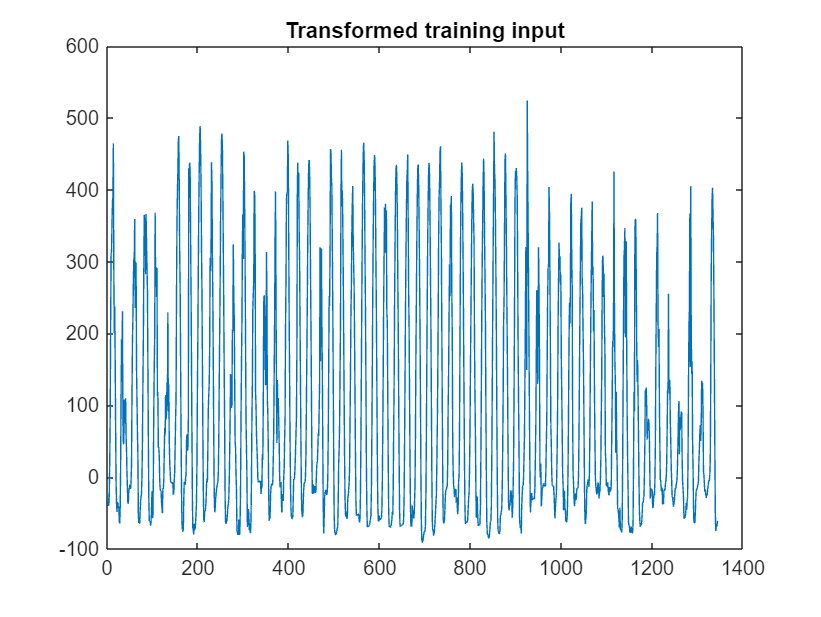

grpStr = num2str( groupNo );
switch length(grpStr)
    case 1       
        grpStr = append("00", grpStr); 
    case 2       
        grpStr = append("0", grpStr); 
end
grpStr = append("group", grpStr);
addpath('../functions', '../data', grpStr)              % Sets the path to your code.

InputInd=data(:,6);
DataInd=data(:,8);
Data=DataInd(1:50000);
DataTestInd=50001:60624;
DataTest=DataInd(50001:end);                          % Leave some data to test the predictor
Input=InputInd(1:50000);
InputTest=InputInd(DataTestInd);

trainDataInd = 30025:30024+sweek*8;                     % Select some training data; these 8 weeks seems nice.
trainingData = Data(trainDataInd);                      % Notice that the model is build on only the training data.
trainingInput = Input(trainDataInd);


figure, plot(trainingInput),		
title('Transformed training input');

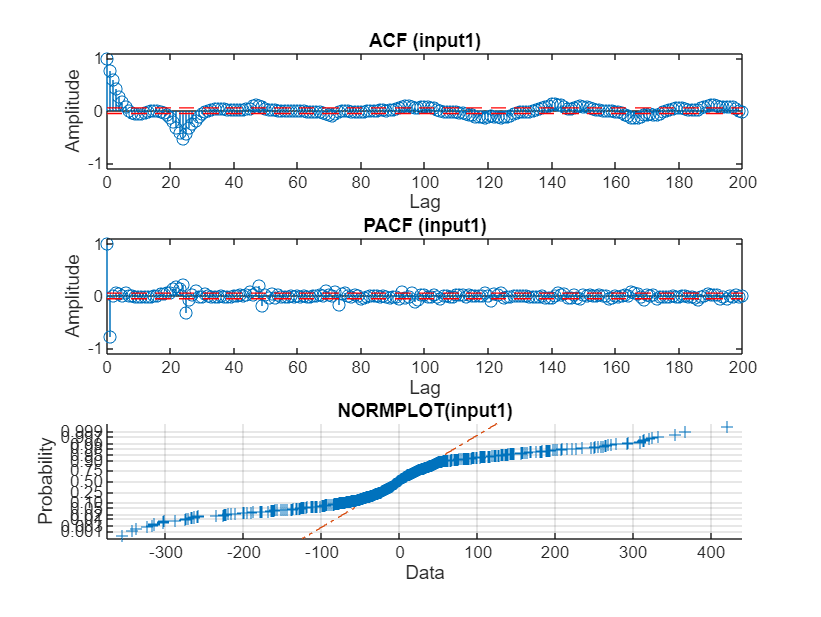

% Part B: Box-Jenkins Model
A24=[1 zeros(1,23) -1];
yd=filter(A24,[1],trainingData);
yd=yd(25:end);
myd=iddata(yd);
ud=filter(A24,[1],trainingInput);
ud=ud(25:end);
mud=iddata(ud);
% Time to model input.
acfs(mud.y,nolags,'input1');

% a1 definetely will be one parameter.
m1ii=idpoly([1 0],[],[1]);
m1im=pem(mud,m1ii);
present(m1im)

m1im =
Discrete-time AR model: A(z)y(t) = e(t)
  A(z) = 1 - 0.7705 (+/- 0.01756) z^-1 
                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1
   Number of free coefficients: 1
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 2, Number of function evaluations: 87   
                                                              
Estimated using PEM on time domain data "mud".                
Fit to estimation data: 36.24% (prediction focus)             
FPE: 2708, MSE: 2704                                          
More information in model's "Report" property.
 


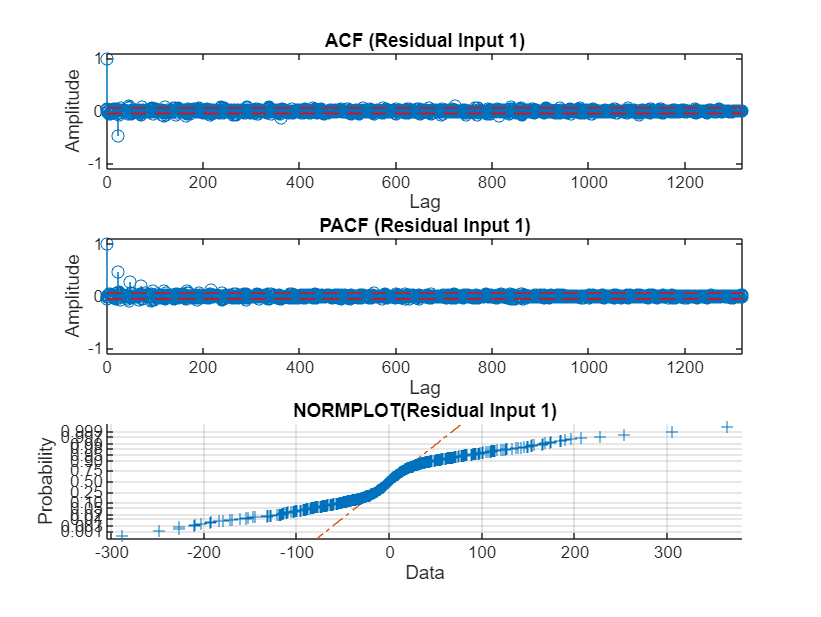

res1i=resid(m1im,mud);
acfs(res1i.y,length(res1i.y),'Residual Input 1');

% c24 need to be put into model.
m1ii=idpoly([1 0],[],[1 zeros(1,24)]);
m1ii.Structure.c.Free=[0 zeros(1,23) 1];
m1im=pem(mud,m1ii);
present(m1im)

m1im =
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)
  A(z) = 1 - 0.7444 (+/- 0.01891) z^-1       
                                             
  C(z) = 1 - 0.8188 (+/- 0.01613) z^-24      
                                             
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nc=24
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 5, Number of function evaluations: 11   
                                                              
Estimated using PEM on time domain data "mud".                
Fit to estimation data: 49.43% (prediction focus)             
FPE: 1706, MSE: 1700                                          
More information in model's "Report" property.
 


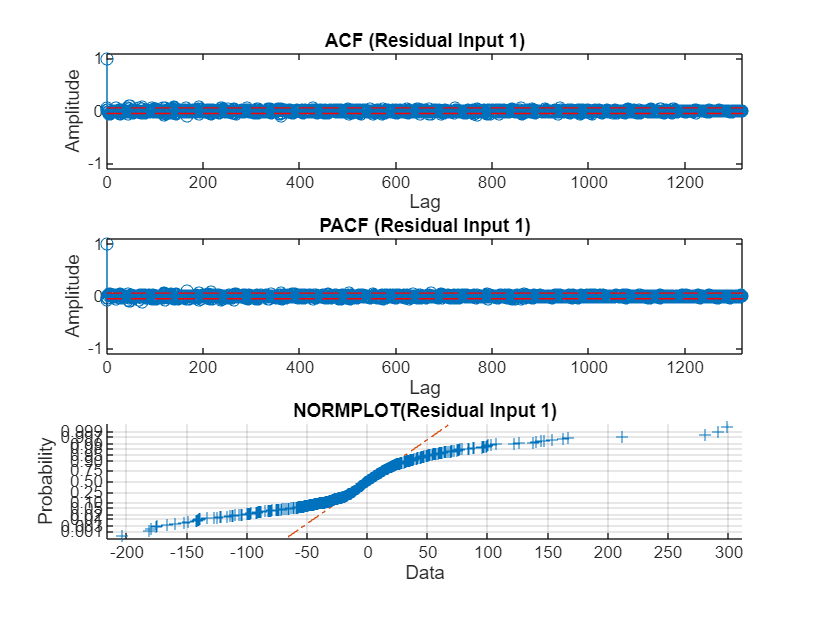

res1i=resid(m1im,mud);
acfs(res1i.y,length(res1i.y),'Residual Input 1');

checkIfWhite(res1i.y)

The residual is deemed to be WHITE according to the Monti-test (as 23.47 < 31.41).


ans = logical
   1


The D'Agostino-Pearson's K2 test indicates that the Agostino-Pearson is NOT normal distributed.


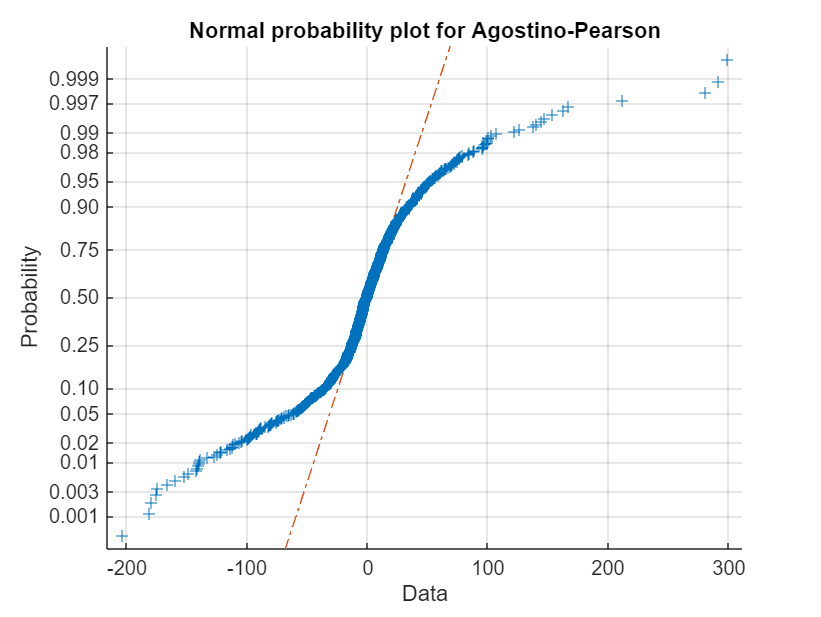

ans = logical
   0


checkIfNormal(res1i.y,'Agostino-Pearson')

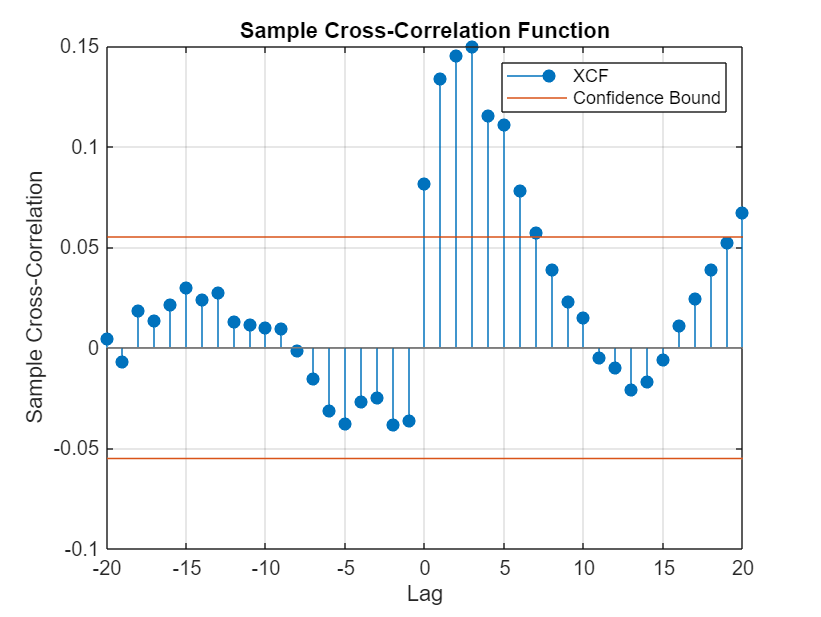

%model the correlation
w1t=filter(m1im.a,m1im.c,mud.y);
crosscorr(w1t,myd.y)

%so we choose d=0, r=2, s=3
A2=[1 0 0];
B=[1 0 0 0];
m1bi=idpoly([1],[B],[],[],[A2]);
m1bi=idpoly([1],[B],[],[],[A2]);
z=iddata(yd,ud);
m1bm=pem(z,m1bi);
present(m1bm)

m1bm =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                       
  B(z) = 0.002717 (+/- 0.001118) + 0.00414 (+/- 0.001394) z^-1 + 0.001335 (+/- 0.00112) z^-2 + 0.0007448 (+/- 0.002195) z^-3
                                                                                                                            
  F(z) = 1 + 0.1093 (+/- 0.4131) z^-1 - 0.3133 (+/- 0.5989) z^-2                                                            
                                                                                                                            
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nf=2   nk=0
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 4, Number of functi

etilda=resid(m1bm,z);
M=30;
n=length(ud);
figure
subplot(1,1,1)
stem(-M:M,crosscorr(w1t,etilda.y,M));

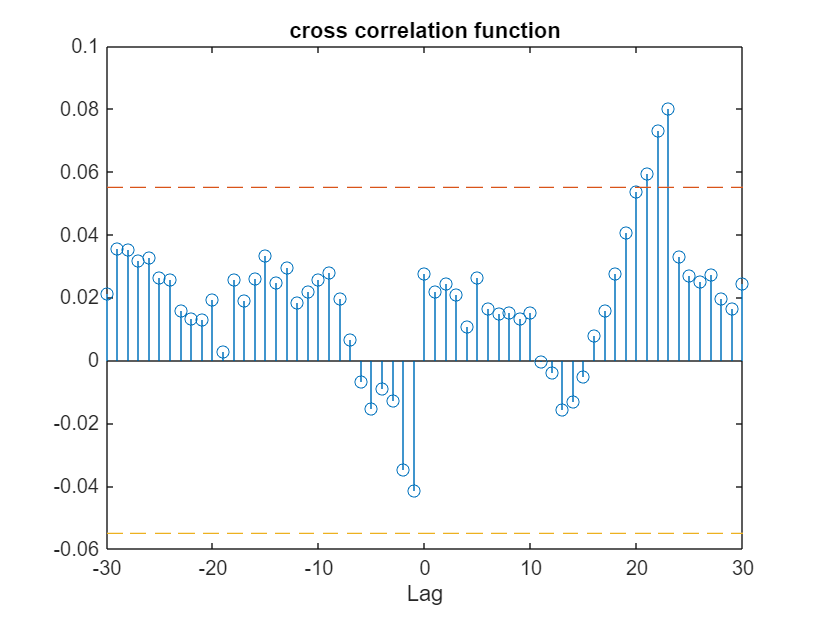

title('cross correlation function')
xlabel('Lag')
hold on
plot(-M:M,2/sqrt(n)*ones(1,2*M+1),'--')
plot(-M:M,-2/sqrt(n)*ones(1,2*M+1),'--')
hold off

% s=3 is seems not so good. So we try d=0, r=2, s=4.
A2=[1 0 0];
B=[1 0 0 0 0];
m1bi=idpoly([1],[B],[],[],[A2]);
m1bi=idpoly([1],[B],[],[],[A2]);
z=iddata(yd,ud);
m1bm=pem(z,m1bi);
present(m1bm)

m1bm =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                                                         
  B(z) = 0.003679 (+/- 0.001159) + 0.002849 (+/- 0.001745) z^-1 - 0.001637 (+/- 0.0008208) z^-2 - 0.001647 (+/- 0.001316) z^-3 - 0.001748 (+/- 0.0008301) z^-4
                                                                                                                                                              
  F(z) = 1 - 0.3399 (+/- 0.4437) z^-1 - 0.6277 (+/- 0.4089) z^-2                                                                                              
                                                                                                                                                              
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   nb=5   nf=2   nk=0
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties

etilda=resid(m1bm,z);
M=30;
n=length(ud);
figure
subplot(1,1,1)
stem(-M:M,crosscorr(w1t,etilda.y,M));

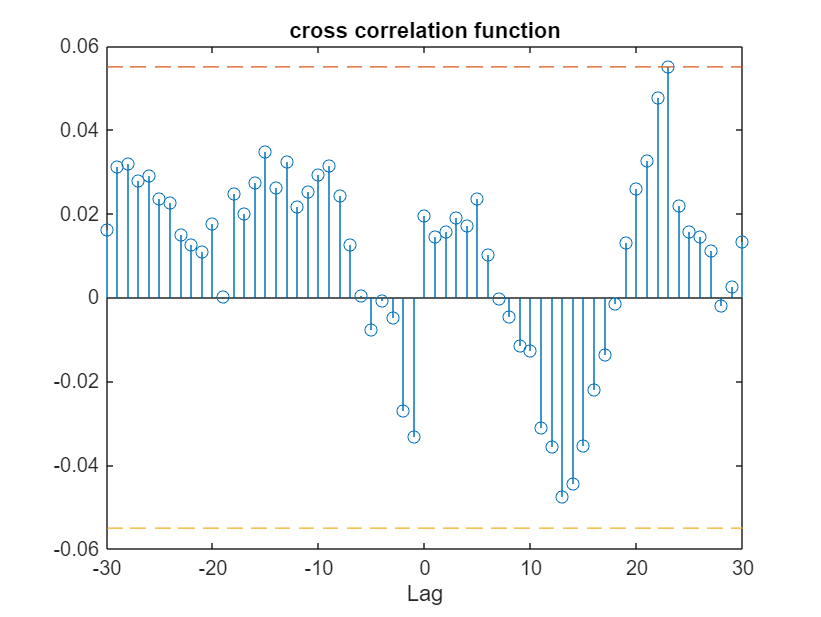

title('cross correlation function')
xlabel('Lag')
hold on
plot(-M:M,2/sqrt(n)*ones(1,2*M+1),'--')
plot(-M:M,-2/sqrt(n)*ones(1,2*M+1),'--')
hold off

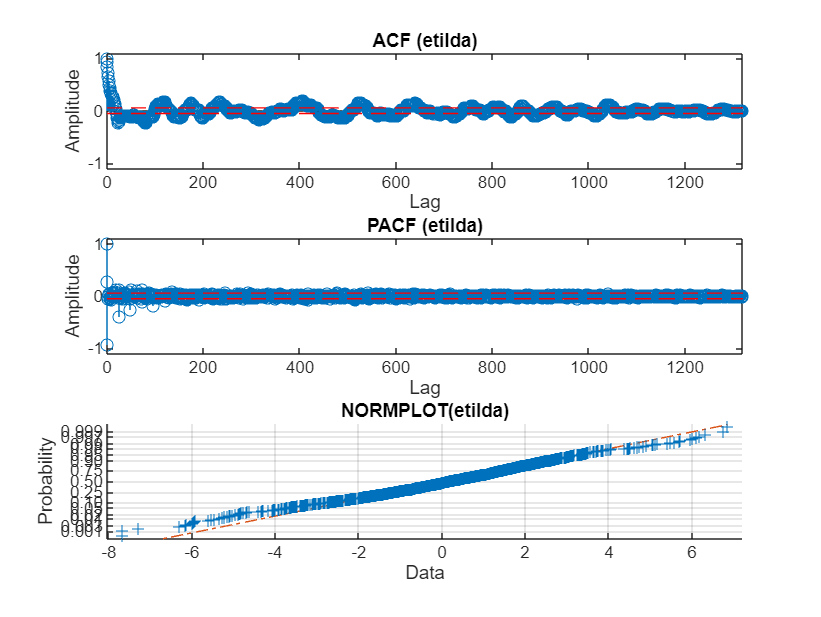

%now we get the etilda and w1t not crrelated. 
etilda2=iddata(etilda.y);
acfs(etilda2.y,length(etilda2.y),'etilda');

m1oi=idpoly([1 0 0],[],[1 zeros(1,24)]);
m1oi.Structure.c.Free=[0 zeros(1,23) 1];
m1om=pem(etilda2,m1oi);
present(m1om)

m1om =
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                  
  A(z) = 1 - 1.248 (+/- 0.0266) z^-1 + 0.2921 (+/- 0.0266) z^-2
                                                               
  C(z) = 1 - 0.8814 (+/- 0.01344) z^-24                        
                                                               
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nc=24
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 5, Number of function evaluations: 11   
                                                              
Estimated using PEM on time domain data "etilda2".            
Fit to estimation data: 74.2% (prediction focus)              
FPE: 0.3031, MSE: 0.3017                                      
More information in model's "Report" 

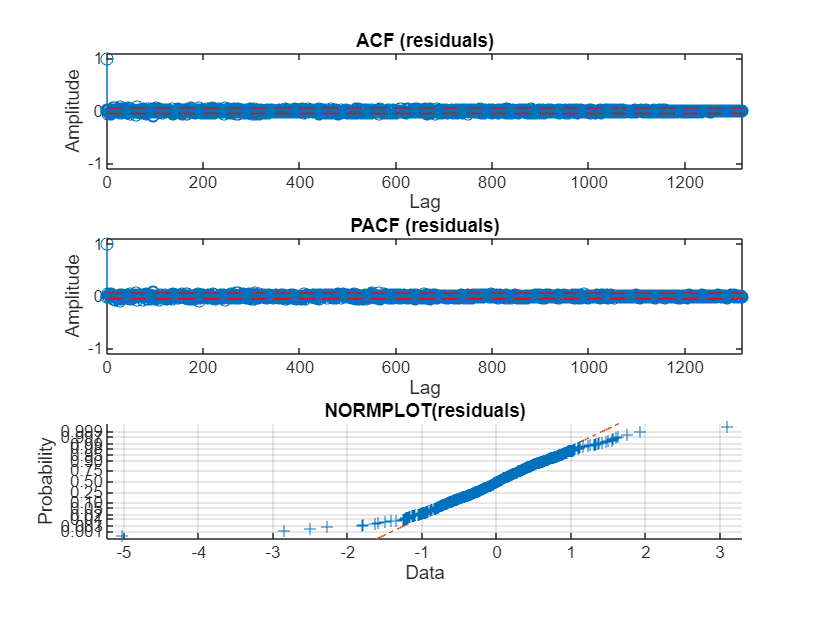

res1o=resid(m1om,etilda2);
acfs(res1o.y,length(res1o.y),'residuals');

checkIfWhite(res1o.y)

The residual is deemed to be WHITE according to the Monti-test (as 24.34 < 31.41).


ans = logical
   1


The D'Agostino-Pearson's K2 test indicates that the Agostino-Pearson is NOT normal distributed.


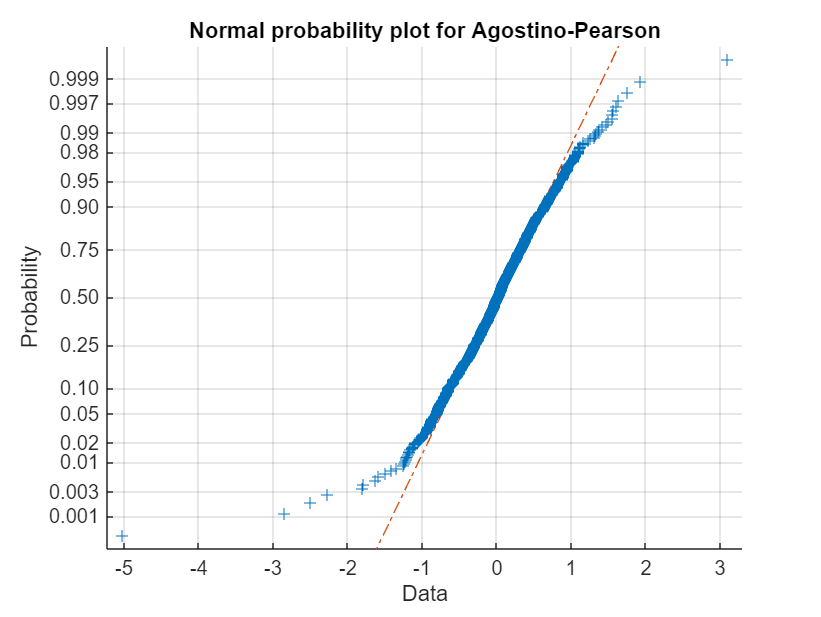

ans = logical
   0


checkIfNormal(res1o.y,'Agostino-Pearson')

%now we begin to reestimate the whole model.
A1=[1 0 0];
C=[1 zeros(1,24)];
mi=idpoly(1,B,C,A1,A2);
mi.Structure.c.Free=[0 zeros(1,23) 1];
Mbj=pem(z,mi);
present(Mbj)

Mbj =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                                                                                 
  B(z) = 0.006345 (+/- 0.0003722) + 0.001092 (+/- 0.001492) z^-1 - 0.002509 (+/- 0.0006055) z^-2 - 0.0007746 (+/- 0.0006055) z^-3 - 0.001394 (+/- 0.0003964) z^-4
                                                                                                                                                                 
  C(z) = 1 - 0.8644 (+/- 0.01429) z^-24                                                                                                                          
                                                                                                                                                                 
  D(z) = 1 - 1.262 (+/- 0.02664) z^-1 + 0.3072 (+/- 0.02664) z^-2                                                                                                
                      

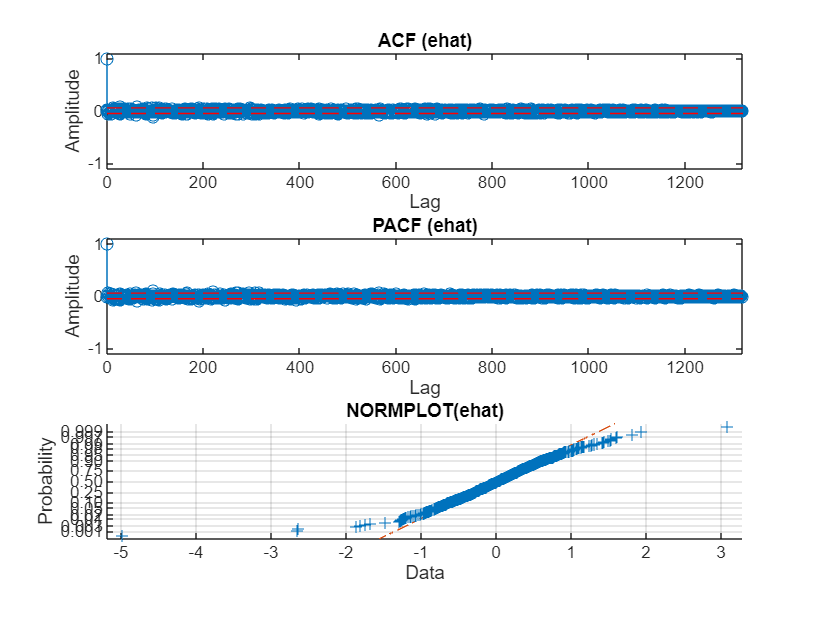

ehat=resid(Mbj,z);
acfs(ehat.y,length(ehat.y),'ehat');

checkIfWhite(ehat.y)

The residual is deemed to be WHITE according to the Monti-test (as 25.75 < 31.41).


ans = logical
   1


The D'Agostino-Pearson's K2 test indicates that the Agostino-Pearson is NOT normal distributed.


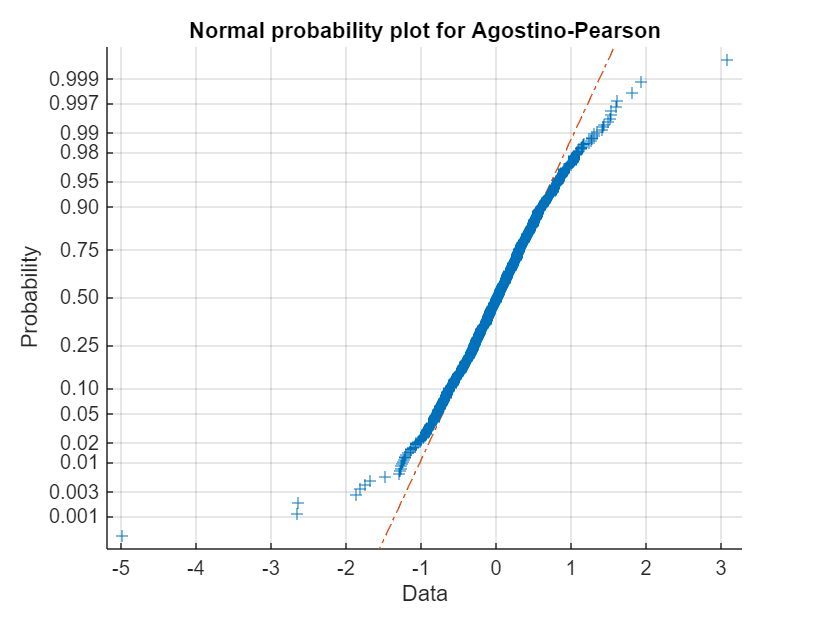

ans = logical
   0


checkIfNormal(ehat.y,'Agostino-Pearson')

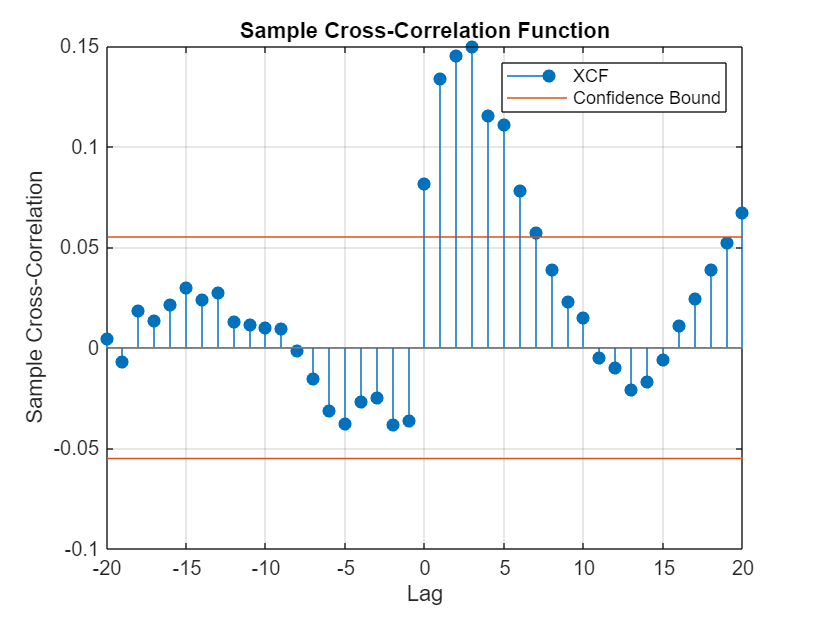

%prediction
%predict the input
mxa=conv(A24,m1im.a);

[Fix,Gix]=polydivision(m1im.c,mxa,k);
[Fux,Gux]=polydivision(m1im.c,m1im.a,k);
Inputhat=filter(Gix,m1im.c,Input);
u=filter(A24,[1],Input);
uhat=filter(Gux,m1im.c,u);
figure(5)
subplot(1,1,1)

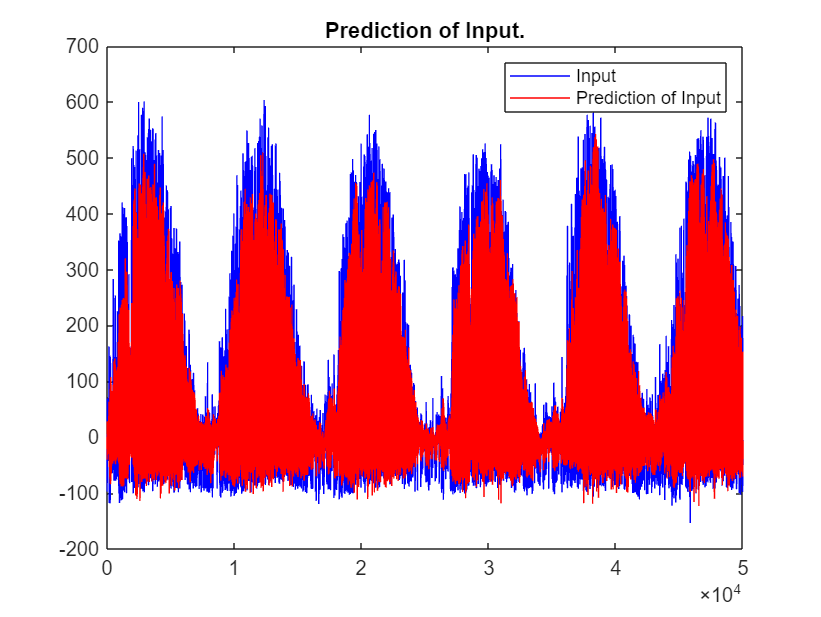

plot(1:length(Input),Input,'b');
hold on
plot(1:length(Input),Inputhat,'r');
hold off
title('Prediction of Input.')
legend('Input','Prediction of Input')

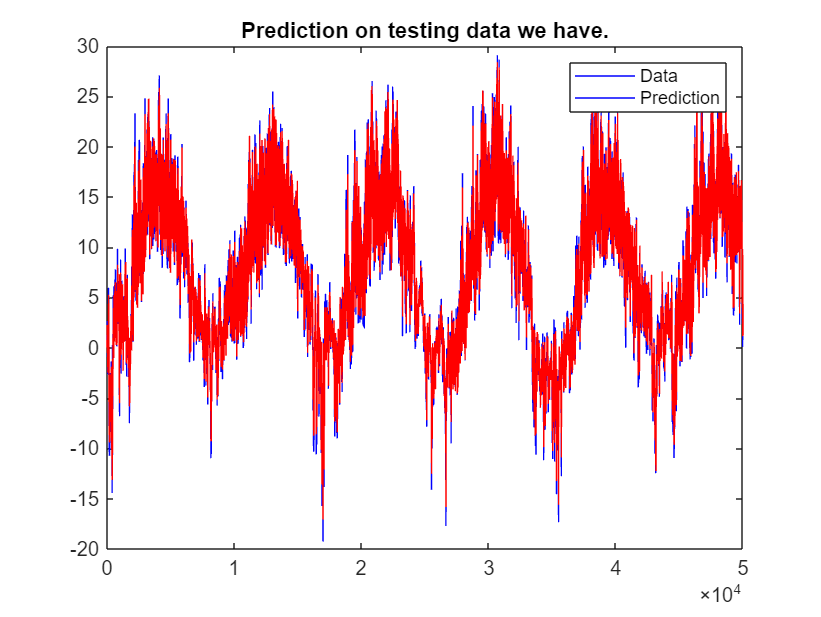

%predict the output on the validation data.
[F,G]=polydivision(Mbj.c,conv(Mbj.d,A24),k);
BF=conv(Mbj.b,F);
[Fhat,Ghat]=polydivision(BF,Mbj.c,k);
yhatt1=filter(Fhat,[1],uhat);
yhatt2=filter(Ghat,Mbj.c,u);
yhatt3=filter(G,Mbj.c,Data);
yhat=yhatt1+yhatt2+yhatt3;

figure(6)
subplot(1,1,1)
plot(1:length(yhat),Data,'b');
hold on
plot(1:length(yhat),yhat3,'r');
hold off
title('Prediction on testing data we have.')
legend('Data','Prediction')

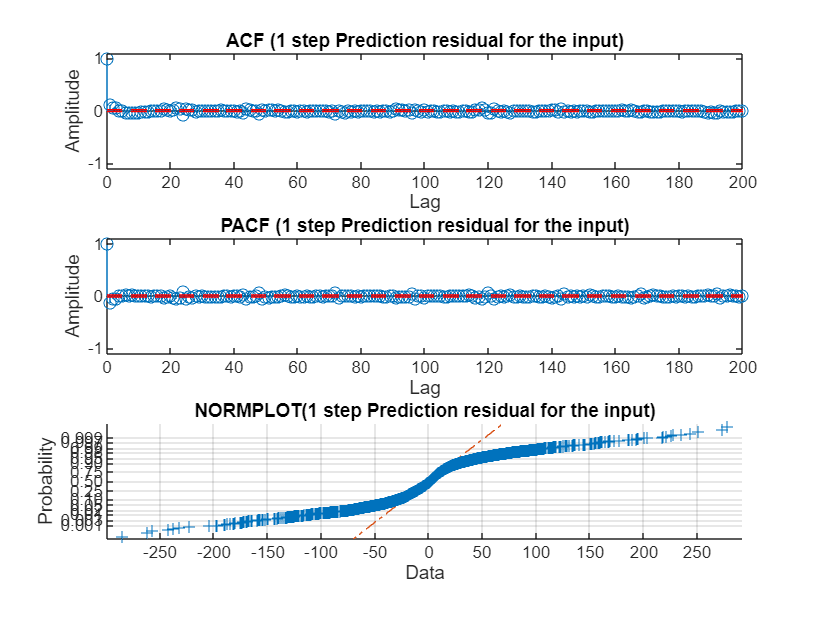

% time to move on to test data.
% first for the input this is 1step prediction
uhat1=predinput_grp049([],InputInd,DataTestInd,1);
ehatA_P1 = InputTest-uhat1;
var_predA_1a = var( ehatA_P1 );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '1 step Prediction residual for the input');

varY = var( InputTest );
fprintf('Prediction results for the 1-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is   14290.85


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is 1108.73. The normalized variance is 0.0776.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 280.27 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


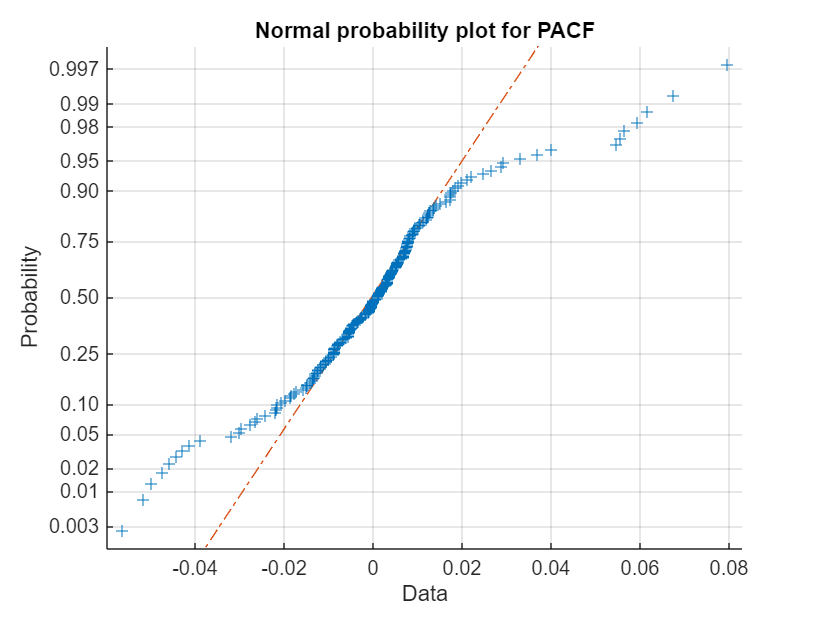

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

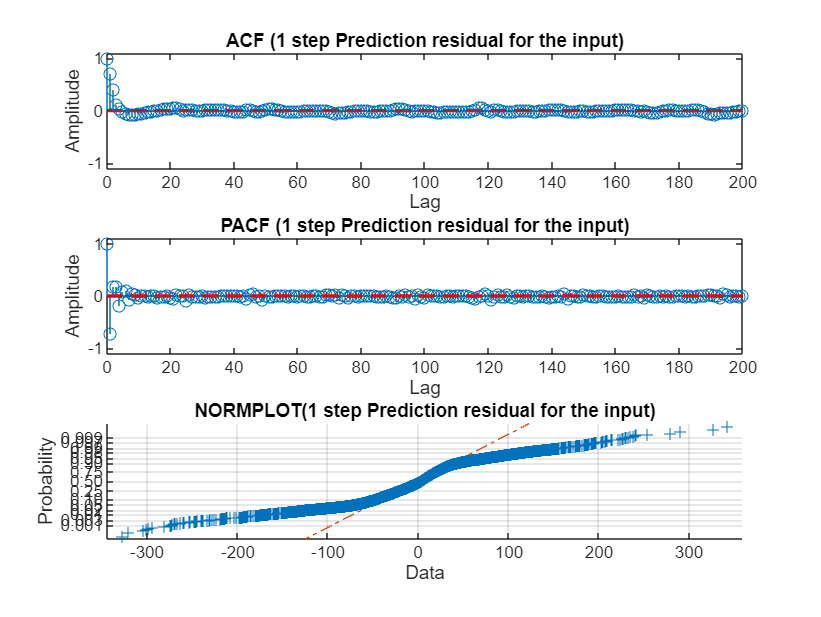

%this is 3 step prediction for the input
uhat3=predinput_grp049([],InputInd,DataTestInd,3);
ehatA_P1 = InputTest-uhat3;
var_predA_1a = var( ehatA_P1 );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '3 step Prediction residual for the input');

varY = var( InputTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is   14290.85


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is 2466.07. The normalized variance is 0.1726.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 6703.56 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


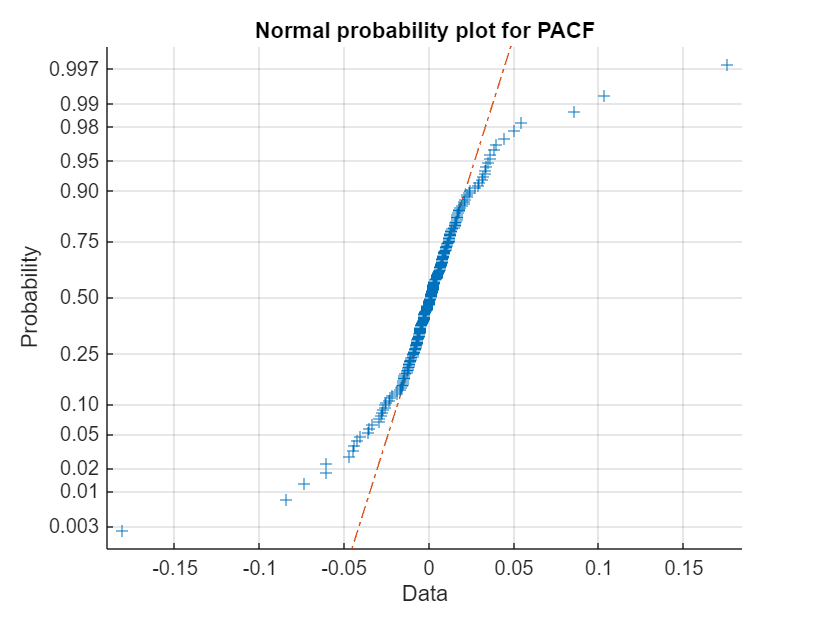

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

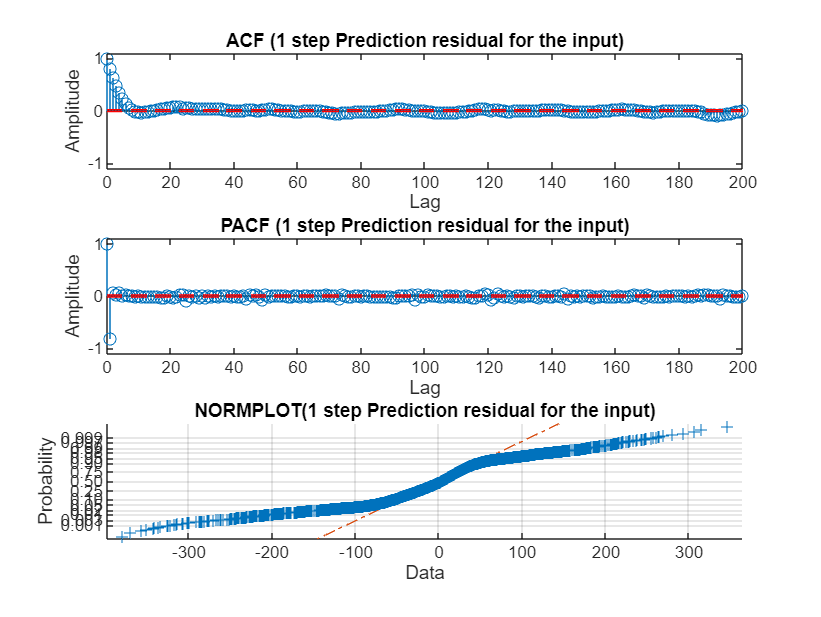

%this is 18 step prediction for the input
uhat18=predinput_grp049([],InputInd,DataTestInd,18);
ehatA_P1 = InputTest-uhat18;
var_predA_1a = var( ehatA_P1 );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '18 step Prediction residual for the input');

varY = var( InputTest );
fprintf('Prediction results for the 18-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is   14290.85


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is 3188.47. The normalized variance is 0.2231.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 7131.12 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


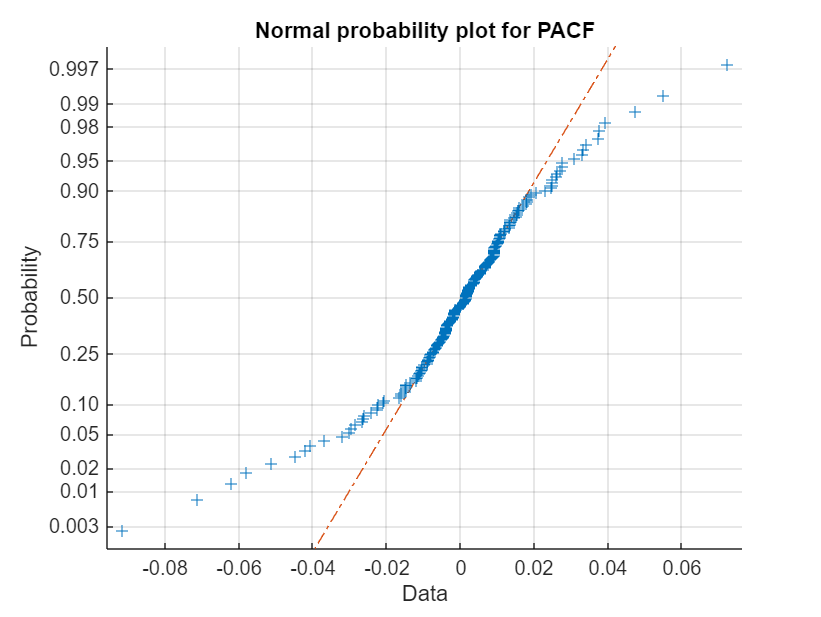

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

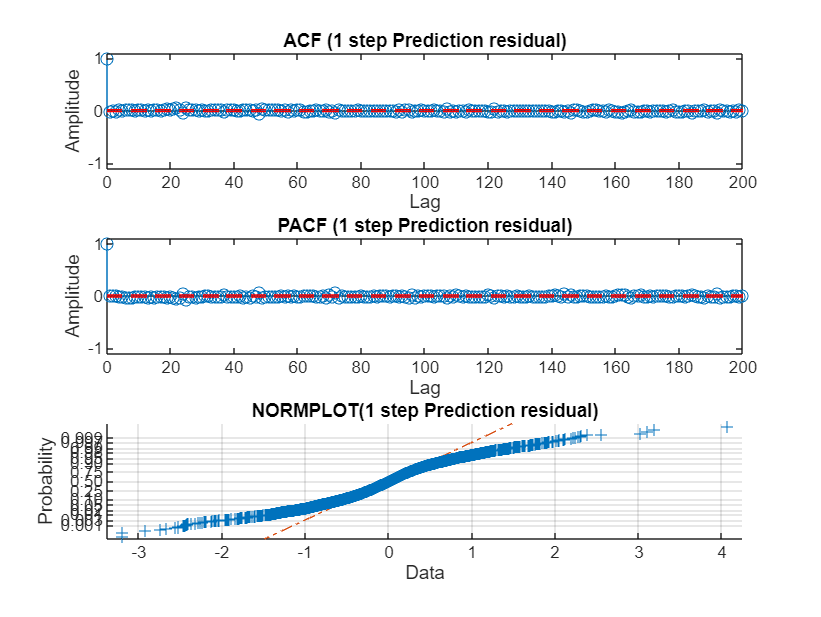

%now move on to the temperature.
%this is the 1 step prediction.
yhat1=predCodeB_grp049(InputInd,DataInd,DataTestInd,1);
ehatA_P1 = DataTest-yhat1;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,1) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '1 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 1-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    0.26. The normalized variance is 0.0069.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    0.44. The normalized variance is 0.0118.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 67.47 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


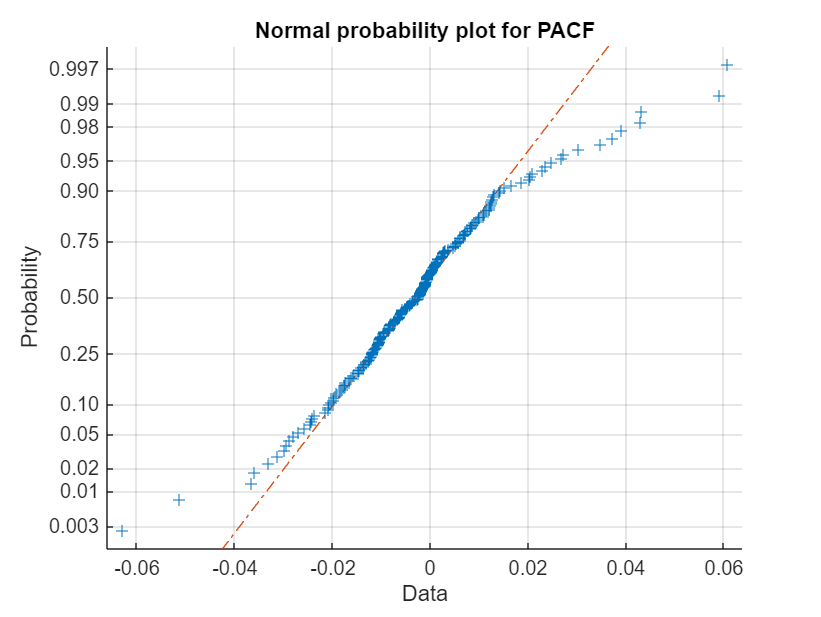

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

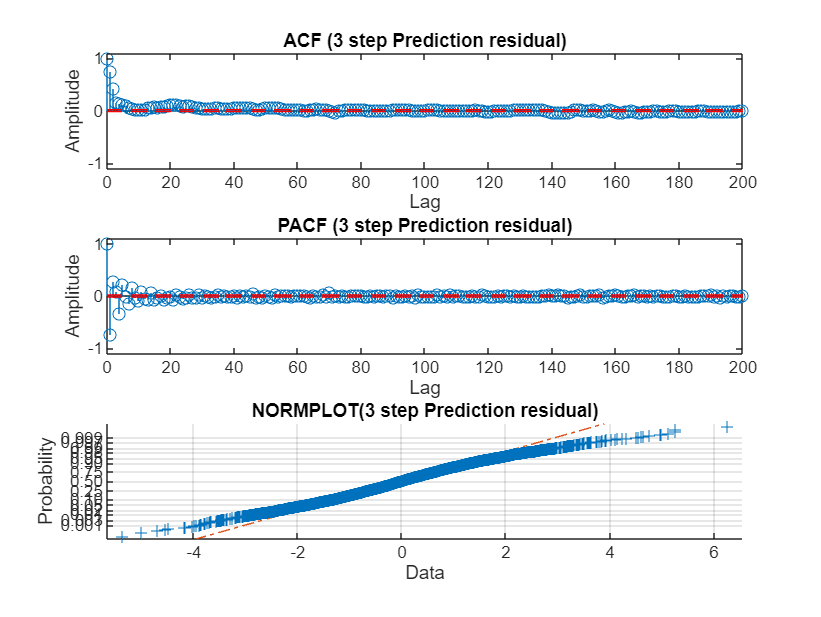

%this is the 3 step prediction.
yhat3=predCodeB_grp049(InputInd,DataInd,DataTestInd,3);
ehatA_P1 = DataTest-yhat3;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,3) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '3 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    1.21. The normalized variance is 0.0322.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    2.72. The normalized variance is 0.0722.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 9274.10 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


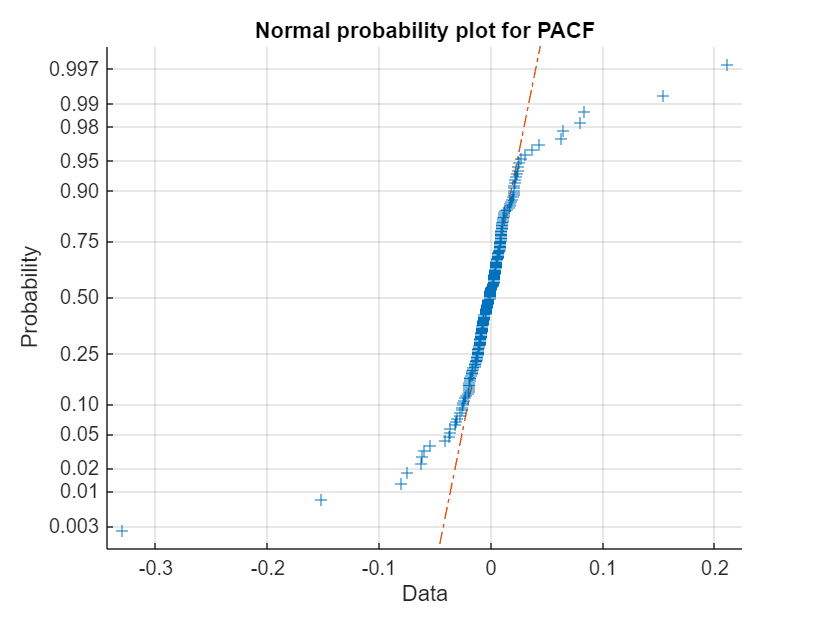

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

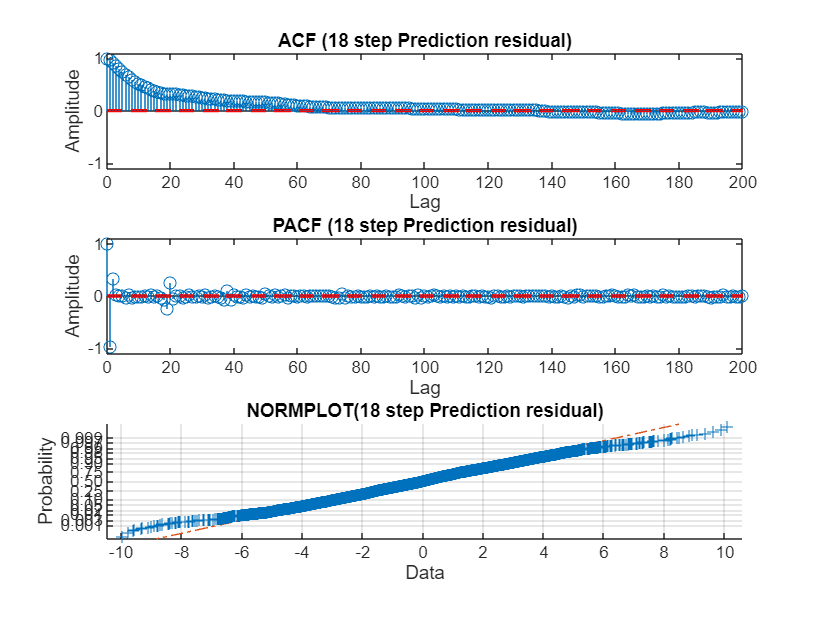

%this is the 18 step prediction.
yhat18=predCodeB_grp049(InputInd,DataInd,DataTestInd,18);
ehatA_P1 = DataTest-yhat18;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,24) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '18 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 18-step prediction:\n')

Prediction results for the 18-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    5.33. The normalized variance is 0.1418.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )

  The variance of the naive predictor is    6.05. The normalized variance is 0.1608.


checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 12625.20 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


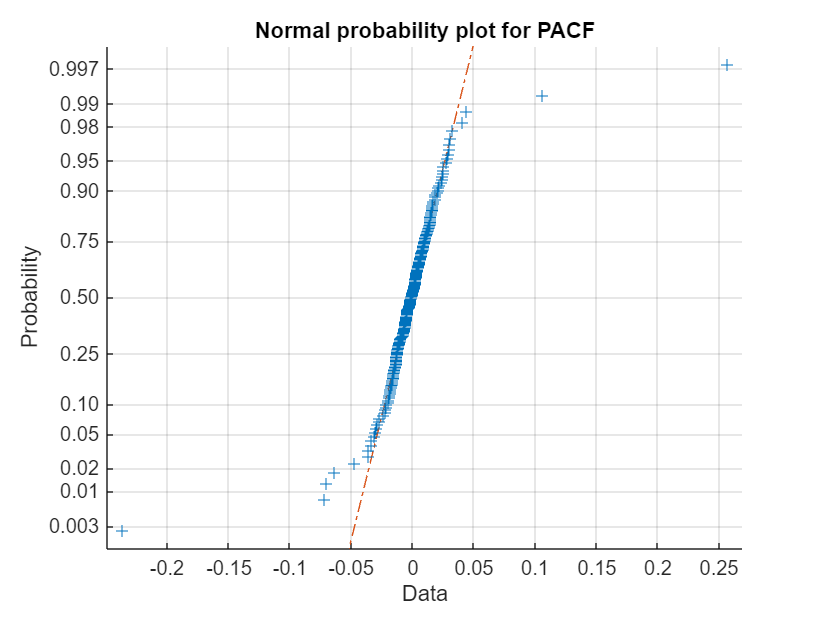

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );